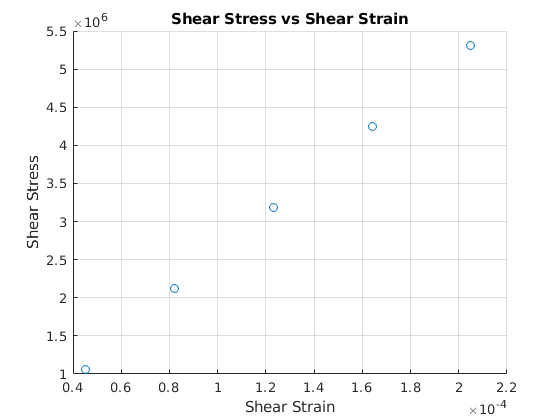

load torsion.mat;
force = torsion.Load;       % load in (N)
H = 0.001*torsion.h;          % Vertical deflection of torque arm at gage location (m)
eps0 = 10^(-6)*torsion.strain_0;
eps45 =10^(-6)*torsion.strain_45;
eps90 =10^(-6)*torsion.strain_90;
r = 0.010;       % radius of rod (m)
d = 0.170;       % torque arm(m)
L = 0.687;       % Length of the rod between two fixed ends (m)
S = 0.135;         % Arm length till the location of the deflection gage (m)
J = (pi*r^4)/2 ;    % m^4
%%%%%%%%%%%%%%%%%%%%%%%%%
gamaxy = zeros(length(H),1);
Theta = zeros(length(H),1);
Torque = zeros(length(H),1);
stress = zeros(length(H),1);
for i=1:length(H)
    gamaxy(i) = 2*eps45(i)-eps0(i)-eps90(i);
    Theta(i)  = atan(H(i)/S);
    Torque(i) = 2*force(i)*d;
    stress(i) = (r/J)*Torque(i);
    
end
clear i
figure
scatter(gamaxy,stress);
grid on
xlabel('Shear Strain');
ylabel('Shear Stress');
title('Shear Stress vs Shear Strain');

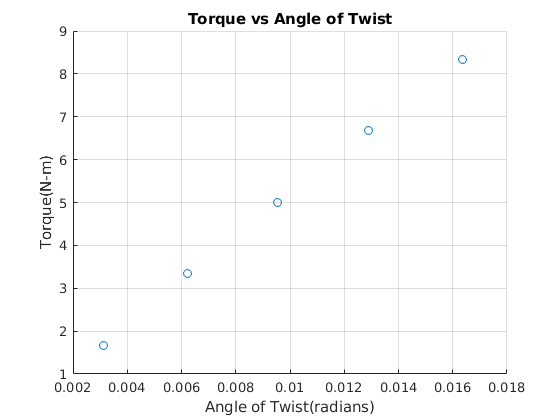


scatter(Theta,Torque);
slope = polyfit(Theta,Torque,1);
G = (slope*L)/J;
xlabel('Angle of Twist(radians)');
ylabel('Torque(N-m)');
title('Torque vs Angle of Twist');
grid on